# Introduction to Neural Networks

## What are neural networks?

### The analogy of the neuron

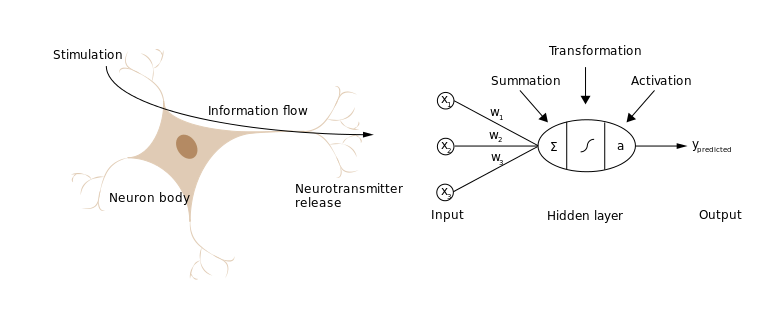

We can describe the intuition of a neural network by looking at how neurons relay and process information to cause a physiological response. Initially, a neuron takes in some stimulation (ie staring at your exam), and channels an electrical signal across the cell to release chemical signals (neurotransmitters) to adjacent neurons. This signal is sent from the initial starting point until it reaches a processing center in the brain, where a decision is made to elicit a specific physiological response (ie increased heart rate, sweaty palms, etc) based on the stimulus. 

Similarly, neural networks perform a similar processing strategy to either categorize labeled data or output continuous values. To summarize the procedure of a neural network algorithm, it takes in an **input** dataset $X$, where each feature is represented as a node ($x_1 ,x_2 ,\textrm{and}\;x_3$ in the diagram above). 

The layer were the data processing occurs is called the **hidden layer**, as the intermediate "features" are not shown in the final model output. Using pre-defined **weights **($w_1 ,w_2 ,\textrm{and}\;w_3$), the data is processed in the middle layer through iterative summations, linear transformations, and applying a non-linear function on the transformed data, generating new "features". These new features are fed into subsequent layers that continuously transformed until we reach the **output layer**. The final resulting values from each transformation can be classified based on some pre-determined thresholds or kept as continuous values. 

The next sections go over common representations and notation for neural networks, the specific steps of the neural network algorithm, and finally an example working with a toy model to output the final predicted values. 

### The components and notation of a feed-forward neural network

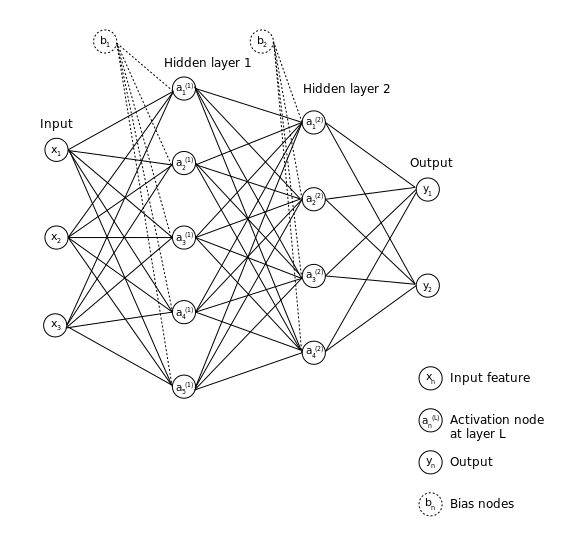

There are [several flavors of neural networks](https://towardsdatascience.com/the-mostly-complete-chart-of-neural-networks-explained-3fb6f2367464), each one having their own advantages and disadvantages and used to solve different problems. The diagram above displays a **feed-forward neural network**, which is a base model that can be a building block to other neural net variations. 

**Each component is described below:**

Input layer: the data ($X_{\textrm{train}}$) we are training the neural network on, where each $n^{\textrm{th}}$ column or feature vector represents a node in the network digram. The diagram above  shows 3 features.

Hidden layer(s): where the features are transformed into new representations that are closer to the "true" value.

- Each **activation node** ($a_n$) represents our newly determined complex feature vector. A single hidden layer can consist of several activation nodes that may not necessarily correspond to the number of predictors we are inputting into the model. 

- The **bias nodes** ($b_n$) can be a scalar or vector of values that further influences the model fit. 

The digram above shows a neural networks with several hidden layers. These are known as **deep neural networks**. To illustrate the basic computations, however, we'll only be dealing with a **shallow neural network** that contains 1 hidden layer. 

Output layer: the final computed values after processing the input data through the hidden layers. 

## The toy shallow neural network

For the next couple of sections, we will illustrate the process of training a shallow neural network using the Framingham dataset to predict patient outcomes, such as if a patient received a stroke or not with the following components: 

- **Input data:** The Framingham heart disease dataset

- **Hidden layer:** 1 layer with 5 activation nodes

- **Biases:** Assume no biases ($b_1 =0$)

- **Output:** If a patient receives a stroke

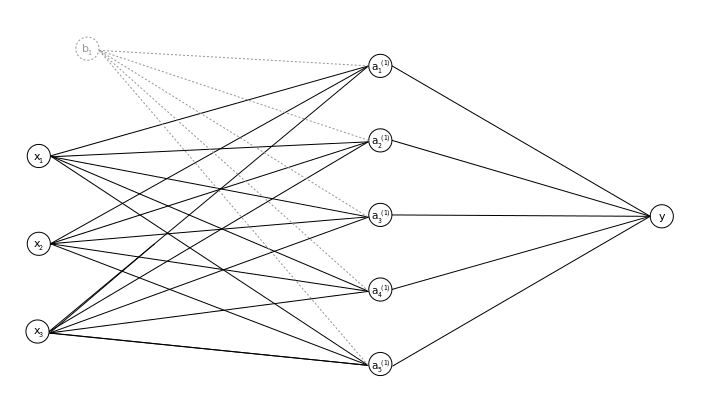

To use the code in the following modules, load the Framingham dataset and process the dataset:

% Read in the datasetand and remove rows that contain NaN
data = readtable('frmgham.xls');
data = rmmissing(data);

X = data(:, 1:24);
Y = data(:, 39);

trainingSize = 0.8;
randomState = false;
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X, Y, trainingSize, randomState);

## Overview of Neural Network Implementation

A summary of the steps to train a neural network are outlined below:

- **Intialize weights** for each connection between nodes in different layers

- **Forward propagation:** Feed the input data into an activation node, to get the the fitted value from the activation function

- **Use the cost function **to compute the error between the activation node and the actual observed value for y

- **Backpropagation**: Compute the cost for each iteration for forward propagation and minimize the error using gradient descent.

### Forward Propagation

**The goal of forward propagation is to compute our hypothetical values through chained linear and non-linear transformations.**

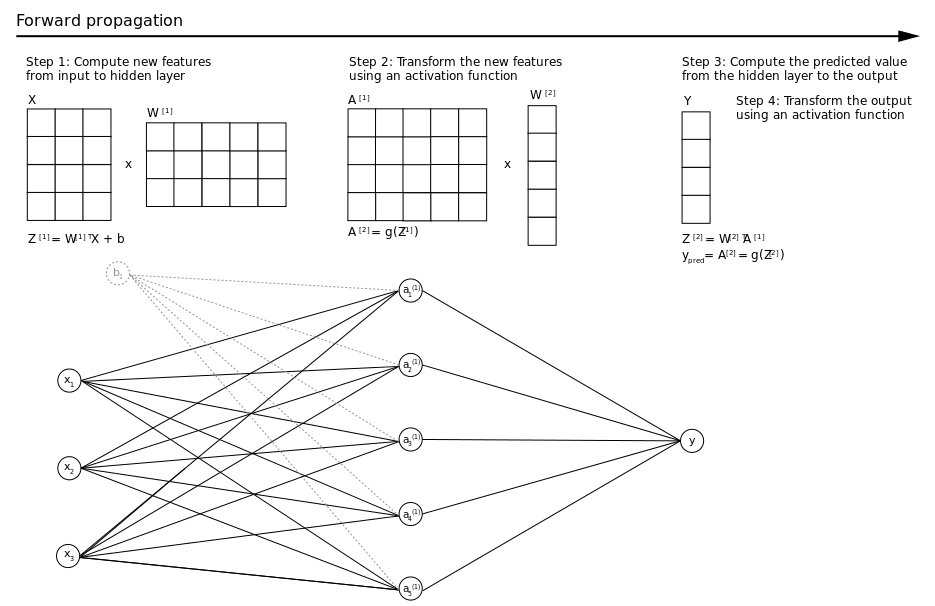

**Step 1: Compute new features from the input layer to hidden layer through linear transformations **

The first step is to linearly transform the input data into a new feature based on two parameters: the weight matrix $W$, and the bias vector $b$. The transformed data will be stored in a temporary variable, usually denoted as $Z^{\left\lbrack n\right\rbrack }$, where $n$ refers to the specific layer in the neural network. The linear equation is described below, and essentially breaks down to the linear regression model at first glance:


$$Z^{\;\left\lbrack 1\right\rbrack } =W^{\left\lbrack 1\right\rbrack \;T} X+b$$


Because we're assuming no biases in our toy model, $b=0$, and the expression simplifies to


$$Z^{\;\left\lbrack 1\right\rbrack } =W^{\left\lbrack 1\right\rbrack \;T} X$$


**Step 2: Perform a non-linear transformation of **$Z$** using the activation function **$g\left(\cdot \right)$

The second step, however, is unique in that we further transform the data using a non-linear activation function $g\left(\cdot \right)$.


$$A^{\;\left\lbrack 1\right\rbrack } =g\left(Z^{\;\left\lbrack 1\right\rbrack } \right)$$


Traditionally, the sigmoid activation function $g\left(Z\right)=\frac{1}{1+e^{-Z} }$ was commonly used as a binary classifier, as is commonly used in logistic regression. However, Rectified Linear Units (ReLUs) are now more commonly used, and are discussed in further sections. 

**Step 3 and 4: Repeat until we reach the output layer**

The subsequent linear and nonlinear transformations will depend on how many layers are in the neural network. For our model, we can compute the second linear transformation, followed by the last non-linear transformation that will give us our predicted values.


$$Z^{\;\left\lbrack 2\right\rbrack } =W^{\left\lbrack 2\right\rbrack \;T} A^{\;\left\lbrack 1\right\rbrack }$$



$${y_{\textrm{predicted}} \;=A}^{\;\left\lbrack 2\right\rbrack } =g\left(Z^{\;\left\lbrack 2\right\rbrack } \right)$$


#### Bias nodes

Note that the bias term is analagous to the intercept in a linear regression model, and serves the same function - to bias the value with a different starting value than 0. This is important if we consider the case of sparse datasets, where there are several features in the dataset that contain 0s. If we apply linear transformations on those features, the result will be 0, and we would lose information. Thus, in several cases, the bias value is usually set to 1.

#### Choosing Weights and symmetry breaking

The weight matrix must be non-zero, as we will only be transforming the bias term if all weights were 0. Similarly, if we choose a weight matrix of all 1s, we will be transforming the data only using the activation function several times. A common method to addressing these issues is called **symmetry breaking**, where the weights are biased, non-zero values that are small. These small perturbations help accentuate patterns that exist in the dataset, and will be further accentuated through the next step.  

To perform symmetry breaking, we can initial the first weight matrix $W^{\left\lbrack 1\right\rbrack \;}$to be a matrix of random permutations. To have the math work out, the size of this matrix must be the following:

- The number of rows = the number of columns in the dataset 

- The number of columns = the number of activation nodes we're considering in the model. 

The strategies to choose the number of layers and activation nodes in the neural network are discussed below:

#### Choosing the number of activation nodes and the number of layers in the hidden layer

This is a highly debatable subject with [multiple answers](https://machinelearningmastery.com/how-to-configure-the-number-of-layers-and-nodes-in-a-neural-network/), depending on who you ask, and in what context. I simply chose 5 activation nodes because it makes the illustration of the network much easier. However, some [common heuristics that are thrown around](https://www.heatonresearch.com/2017/06/01/hidden-layers.html) are:

- The number of hidden neurons should be between the size of the input layer and the size of the output layer.

- The number of hidden neurons should be 2/3 the size of the input layer, plus the size of the output layer.

- The number of hidden neurons should be less than twice the size of the input layer.

#### Neural Network Activation functions

In this lecture, we will describe two widely-used activation functions: the sigmoid activation function (which you've already encountered in logistic regression), and the Rectified Linear Units or ReLU.

**Sigmoid activation function**

We can use the same logistic function that we used in logistic regression as the activation function, which is denoted as


$$g\left(z\right)=\frac{1}{1+e^{{-\theta }^T z} }$$


This activation function is particularly useful for classification problems, but as you'll see, is limited by the same problems we encountered in logistic regression. Thus, a more recent and widely used activation are ReLUs and their variations.

**Rectified Linear Units (ReLU)**

The idea of the ReLU is simple: for each positive value of $z$, set it to $\max \left(z\right)$. If $z$ is negative, set it to 0


$$g\left(z\right)=\left\lbrace \begin{array}{cc}
\max \left(0,z\right) & \textrm{if}\;z>0\\
0 & \textrm{if}\;z<0
\end{array}\right.$$


#### Forward propagation in MATLAB

The sigmoid activation function used in this example can be called using the `activationFnc.mlx` script:

function A = activationFnc(Z, fnc)
    switch fnc
        case 'Sigmoid'
            A = 1 ./ (1 + exp(-Z));
        case 'ReLU'
            disp('Activation function: ReLu')
            A = max(0, Z);
        case 'Leaky ReLU'
            disp('Activation function: Leaky ReLu')
            A = max(scale, Z);
    end
end

The steps for forward propagation are outlined below.

% Set the weights to be "random", using a default seed for reproducibility.
rng('Default');

% Initialize the parameters used for step 1
numberOfActivationNodes = 5;
W1 = rand([size(Xtrain, 2), numberOfActivationNodes]);
b = zeros(size(Xtrain, 1), 1);

% Step 1: Linear transformation of the data
Z1 = Xtrain * W1 + b;

% Step 2: Activation function for the hidden layer using the Sigmoid
% activation function
A1 = activationFnc(Z1, 'Sigmoid');

% Step 3 and 4: Rinse and repeat
W2 = rand([size(A1, 2), 1]);
Z2 = A1 * W2;
ypred = activationFnc(Z2, 'Sigmoid');

### Cost function to compute model error

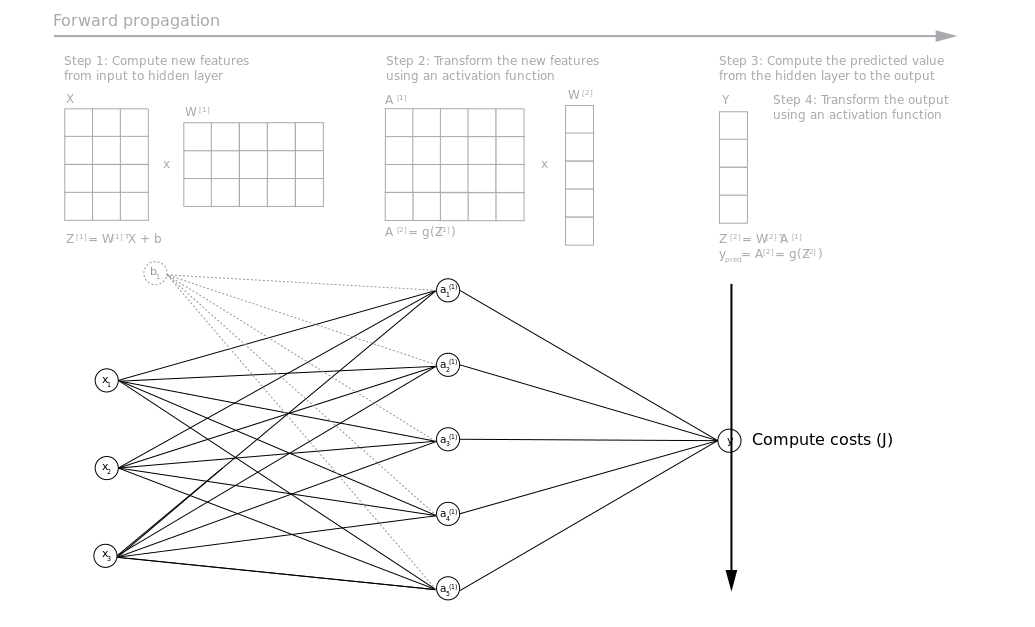

Up until this point, we computed the initial values for $y_{\textrm{pred}}$, and now you may be wondering: why are neural networks useful if we're computing random values? 

The answer is because we haven't truly "learned" the final parameters in a general manner. To do that, we need to compute the error from our model to the true value, and adjust the tuning parameters in the model, $W$ and $b$. Once the values for $W$ and $b$ converge to stable numbers, the final model has optimal values such that it can output values that look like the truth, or compute predicted values. T**he way to compute the error between the model prediction and the true value for our response is the loss function.**

Recall that the loss function is a performance metric on how well our model manages to generate outputs as close as possible to the true values. For the case where we are using the sigmoid activation function, you would want to use the **Cross-Entropy (aka Log-Loss) cost function:**


$$J=-\frac{1}{m}\sum_{i=1}^m \left\lbrack -y^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-y^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack$$


$m$ = number of observations

$y$ = the response variable

$y_{\textrm{pred}}$ = the predicted value for$y$ from forward propagation

The cost can be computed using the code from the `costFunction.mlx` script, which defines the cost function as follows:

function J = costFunction(y, ypred)
    m = length(y);
    
    J = zeros(length(y));
    J = mean(((-y .* log(ypred) - (1 - y) .* log(1 - ypred))));
end

Let's now compute the first cost value from the feedforward values with respect to the value we want to learn:

J = costFunction(Ytrain, ypred);

### Tuning the model using backpropagation and gradient descent 

**Now that we've computed the costs, we can use them to tell the model how to adjust the tuning parameters **$W$** and **$b$**.** This process is called **back propagation, **and the optimization algorithm we will use to get the best values of $W$ and $b$ is called** gradient descent.**

Given the loss value, we need to update $W$ and $b$. To know how much we should adjust these parameters, we need to know the derivative of the loss function with respect to the weights and biases. This can be done using the chain rule:

$\frac{\vartheta J}{\vartheta W}$ = $\frac{\vartheta J}{\vartheta y_{\textrm{pred}} }\cdot \frac{\vartheta y_{\textrm{pred}} }{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta W}$ 

$\frac{\vartheta J}{\vartheta b}$ = $\frac{\vartheta J}{\vartheta y_{\textrm{pred}} }\cdot \frac{\vartheta y_{\textrm{pred}} }{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta b}$ 

We won't go over the full derivation for the partial derivatives of the weight and bias arrays, as it does require a bit of calculus to work through the entire chain. However, the most relevant equations to update the parameters are the following: 


$$\begin{array}{l}
{\mathrm{W}}^{\left\lbrack \mathrm{n}\right\rbrack } ={\mathrm{W}}^{\left\lbrack \mathrm{n}\right\rbrack } -\left(\alpha \cdot d{\mathrm{W}}^{\left\lbrack \mathrm{n}\right\rbrack } \right)\\
{\mathrm{b}}^{\left\lbrack \mathrm{n}\right\rbrack } ={\mathrm{b}}^{\left\lbrack \mathrm{n}\right\rbrack } -\left(\alpha \cdot d{\mathrm{b}}^{\left\lbrack \mathrm{n}\right\rbrack } \right)\\
g^{\prime } \left(Z\right)=A^{\left\lbrack n\right\rbrack } \cdot \left(1-A^{\left\lbrack n\right\rbrack } \right)
\end{array}$$
 

where $n$ is the layer that we're in and $\alpha$ is the **learning rate **(more on that later). The derivative expressions are equal to


$$\begin{array}{l}
{\mathrm{dZ}}^{\left\lbrack \mathrm{n}\right\rbrack } ={A^{n-1} \;-\;A}^n \\
d{\mathrm{W}}^{\left\lbrack \mathrm{n}\right\rbrack } =\mathrm{mean}\left({\mathrm{dZ}}^{\left\lbrack \mathrm{n}\right\rbrack } \cdot A^{\left\lbrack \mathrm{n}\right\rbrack \;T} \right)\\
{db}^{\left\lbrack \mathrm{n}\right\rbrack } =\mathrm{mean}\left({\mathrm{dZ}}^{\left\lbrack \mathrm{n}\right\rbrack } \right)
\end{array}$$


Specifically referring back to our toy model, let's get the expressions for back-calculating better $W$ and $b$ values:


$$\begin{array}{l}
{\mathrm{dZ}}^{\left\lbrack 2\right\rbrack } =A^{\left\lbrack 1\right\rbrack } -Y\\
d{\mathrm{W}}^{\left\lbrack 2\right\rbrack } =\frac{{\mathrm{dZ}}^{\left\lbrack 2\right\rbrack } \cdot A^{\left\lbrack 1\right\rbrack } }{m}\;\\
{\mathrm{dZ}}^{\left\lbrack 1\right\rbrack } =\left(W^{\left\lbrack 2\right\rbrack T} \cdot {\mathrm{dZ}}^{\left\lbrack 2\right\rbrack } \;\right)\cdot g^{\prime } \left({\mathrm{dZ}}^{\left\lbrack 1\right\rbrack } \right)\\
d{\mathrm{W}}^{\left\lbrack 1\right\rbrack } =\frac{{\mathrm{dZ}}^{\left\lbrack 1\right\rbrack } \cdot X}{m}\\
db^{\left\lbrack 1\right\rbrack } =\frac{\mathrm{sum}\left({\mathrm{dZ}}^{\left\lbrack 1\right\rbrack } \right)}{m}\;
\end{array}$$


The way to code this up would be the following:

alpha = 0.05

% Back propagation from output layer back to hidden layer
dZ2 = A1 - ypred;
dW2 = mean(dZ2' * A1);
dY = ypred .* (1 - ypred);

% Update W2
W2 = W2 - (alpha .* dW2)';

% Back propagation from hidden layer to the input layer
dZ1 = (dZ2 * W2) .* dY;
dW1 = dZ1' * Xtrain ./ size(Xtrain, 1);
db = mean(dZ1);

% Update W1 and b
W1 = W1 - (alpha * dW1');
b = b - (alpha * db);

## Putting it all together

% Read in the datasetand and remove rows that contain NaN
data = readtable('frmgham.xls');
data = rmmissing(data);

X = data(:, 1:24);
Y = data(:, 39);

trainingSize = 0.8;
randomState = false;
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X, Y, trainingSize, randomState);

rng('Default');

numberOfActivationNodes = 5;
W1 = rand([size(Xtrain, 2), numberOfActivationNodes])*0.01;
W2 = rand([size(Xtrain, 2), 1])*0.01;
b = zeros(size(Xtrain, 1), 1);
alpha = 0.05;
num_iters = 500;

for i = 1:num_iters
    % Forward propagation    
    Z1 = Xtrain * W1 + b;
    A1 = activationFnc(Z1, 'Sigmoid');
    W2 = rand([size(A1, 2), 1]);
    Z2 = A1 * W2;
    ypred = activationFnc(Z2 , 'Sigmoid');
    
    % Cost function 
    J = costFunction(Ytrain, ypred);
    
    % Backward propagation using gradient descent
    dZ2 = A1 - ypred;
    dW2 = mean(dZ2' * A1);
    dY = ypred .* (1 - ypred);
    
    W2 = W2 - (alpha .* dW2)';
    
    dZ1 = (dZ2 * W2) .* dY;
    dW1 = dZ1' * Xtrain ./ size(Xtrain, 1);
    db = mean(dZ1);
    
    W1 = W1 - (alpha * dW1');
    b = b - (alpha * db); 
end